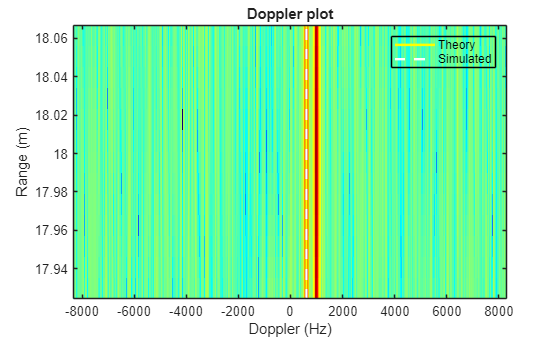

% ======================================================
% Modern Communications Systems
% Project
% Fall 2025
% SCR FMCW Code
%  1. SCR + FMCW Doppler demo (single file)
%  2. SCR Framework
% Process
%  - Simulate one FMCW frame
%  - Output Range–Doppler plot
%  - Output SCR (chirp-splitting and frame-splitting)
% -------------------------------------------------------

clear; clc; close all;

% Waveform parameters
speedOfLight_mps        = 3e8;
carrierFrequency_Hz     = 77e9; % 77 GHz
sweepBandwidth_Hz       = 1.6e9;
chirpRampTime_s         = 60e-6;
adcSampleRate_Hz        = 8e6;
numChirpsPerFrame       = 512;

fmcwWaveform = phased.FMCWWaveform( ...
    'SweepTime',        chirpRampTime_s, ...
    'SweepBandwidth',   sweepBandwidth_Hz, ...
    'SampleRate',       adcSampleRate_Hz, ...
    'SweepDirection',   'Up');

numAdcSamplesPerChirp    = round(chirpRampTime_s * adcSampleRate_Hz);
fastTime_s               = (0:numAdcSamplesPerChirp-1) / adcSampleRate_Hz;
chirpRepetitionTime_s    = chirpRampTime_s;   % Remove idle time

%% Scene: one real target + modulated backscatter (spoofer)
targetRange_m            = 18;
targetRadialVelocity_mps = 1.2;
snr_dB                   = 20;

enableModulatedReturn    = true; % Turn on/off spoofing here
modulationTone_Hz        = 1e3;

targetBeatFreq_Hz        = 2*sweepBandwidth_Hz*targetRange_m/(speedOfLight_mps*chirpRampTime_s);
targetDopplerFreq_Hz     = 2*carrierFrequency_Hz*targetRadialVelocity_mps/speedOfLight_mps;

rxBeatSignal_samplesByChirps = zeros(numAdcSamplesPerChirp, numChirpsPerFrame);

rng(7); % For reproducibility 

for chirpIndex = 1:numChirpsPerFrame
    slowTimePhase_rad = 2*pi*targetDopplerFreq_Hz*(chirpIndex-1)*chirpRepetitionTime_s;
    rxTarget_chirp    = exp(1j*(2*pi*targetBeatFreq_Hz*fastTime_s + slowTimePhase_rad));

    if enableModulatedReturn
        rxModulated_chirp = 0.6 * exp(1j*(2*pi*modulationTone_Hz*(chirpIndex-1)*chirpRepetitionTime_s)) .* ...
                            exp(1j*(2*pi*targetBeatFreq_Hz*fastTime_s));
        rxChirp = rxTarget_chirp + rxModulated_chirp;
    else
        rxChirp = rxTarget_chirp;
    end

    noiseSigma = 10^(-snr_dB/20)/sqrt(2);
    rxChirp = rxChirp + (randn(1,numAdcSamplesPerChirp) + 1j*randn(1,numAdcSamplesPerChirp)) * noiseSigma;

    rxBeatSignal_samplesByChirps(:,chirpIndex) = rxChirp(:);
end

% Range processing
numRangeFftBins          = 4096;
fastTimeWindow           = hann(numAdcSamplesPerChirp);

rangeFft_complex = fft(rxBeatSignal_samplesByChirps .* fastTimeWindow, numRangeFftBins, 1);
rangeMag          = abs(rangeFft_complex);

beatFreqAxis_Hz   = (0:numRangeFftBins-1)'/numRangeFftBins * adcSampleRate_Hz;
rangeAxis_m       = beatFreqAxis_Hz * (speedOfLight_mps*chirpRampTime_s)/(2*sweepBandwidth_Hz);

[~, detectedRangeBin] = max(mean(rangeMag,2));

% Doppler processing
numDopplerFftBins        = 512;
slowTimeWindow           = hann(numChirpsPerFrame).';

rangeBinSlowTime_complex = rangeFft_complex(detectedRangeBin, :);

dopplerSpectrum_complex  = fftshift(fft(rangeBinSlowTime_complex .* slowTimeWindow, numDopplerFftBins, 2), 2);
dopplerAxis_Hz           = (-numDopplerFftBins/2:numDopplerFftBins/2-1)/numDopplerFftBins * (1/chirpRepetitionTime_s);

[~, detectedDopplerIndex]= max(abs(dopplerSpectrum_complex));
detectedDoppler_Hz       = dopplerAxis_Hz(detectedDopplerIndex);

rangeBinHalfWidth_bins   = 6;
rangeBinLow              = max(1, detectedRangeBin - rangeBinHalfWidth_bins);
rangeBinHigh             = min(numRangeFftBins, detectedRangeBin + rangeBinHalfWidth_bins);

rdMap_complex = fftshift(fft(rangeFft_complex(rangeBinLow:rangeBinHigh,:) .* slowTimeWindow, numDopplerFftBins, 2), 2);

figure('Color','w','Name','Range–Doppler (zoom, complex)');
imagesc(dopplerAxis_Hz, rangeAxis_m(rangeBinLow:rangeBinHigh), ...
    20*log10(abs(rdMap_complex)/max(abs(rdMap_complex(:)))));
axis xy
xlabel('Doppler (Hz)')
ylabel('Range (m)');
colormap jet
colorbar
title('Doppler plot')

theoreticalDoppler_Hz = 2*carrierFrequency_Hz*targetRadialVelocity_mps/speedOfLight_mps;

hold on;
yLimits = ylim;
hTheory = plot([theoreticalDoppler_Hz theoreticalDoppler_Hz], yLimits, 'y-',  'LineWidth', 1.8);
hSim    = plot([theoreticalDoppler_Hz theoreticalDoppler_Hz], yLimits, 'w--', 'LineWidth', 1.8);

colorbarHandle = findall(gcf, 'Type', 'Colorbar'); % Colorbar
if ~isempty(colorbarHandle)
    delete(colorbarHandle);
end

legend([hTheory hSim], {'Theory','Simulated'}, ...
    'TextColor','k','EdgeColor','k','Color','none','Location','northeast');
ylim(yLimits);

detectedDoppler_Hz

detectedDoppler_Hz = 618.4896

theoreticalDoppler_Hz

theoreticalDoppler_Hz = 616

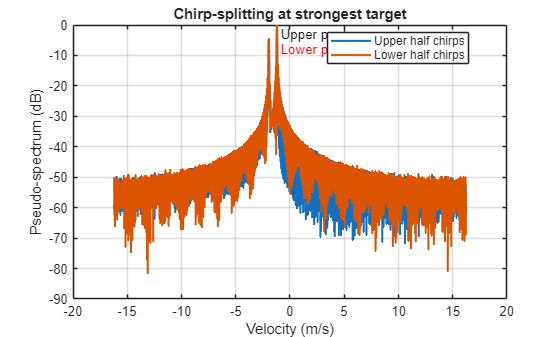

% Create a SCR cube and SCR configurations
rxDataCube_samplesByChirpsByRx = reshape(rxBeatSignal_samplesByChirps, [numAdcSamplesPerChirp, numChirpsPerFrame, 1]);

scrConfig = struct;
scrConfig.fc               = carrierFrequency_Hz;
scrConfig.fs_adc           = adcSampleRate_Hz;
scrConfig.Nfft_range       = numRangeFftBins;
scrConfig.Nfft_doppler     = numDopplerFftBins;
scrConfig.Nv_fine          = 2048;

scrConfig.T_ramp           = chirpRampTime_s;
scrConfig.T_idle_uniform   = 0;
scrConfig.T_idle_jitter    = 0;
scrConfig.BW               = sweepBandwidth_Hz;
scrConfig.k_slope          = sweepBandwidth_Hz / chirpRampTime_s;

scrConfig.t0_lower         = 0.25 * chirpRampTime_s;
scrConfig.t0_upper         = 0.75 * chirpRampTime_s;

scrConfig.RD_threshold        = -20;
scrConfig.velShiftThresh_Hz   = 5;
scrConfig.distMagDiffThresh   = 0.5;

% Run SCR on the frame
scrOutput = scr_run_frame(rxDataCube_samplesByChirpsByRx, scrConfig);

% Plot SCR RD map (extra)
% figure('Color','w','Name','SCR Range–Doppler');
% imagesc(scrOutput.vel_axis, scrOutput.range_axis, ...
%     20*log10(scrOutput.RD_standard ./ max(scrOutput.RD_standard(:))));
% axis xy
% colormap jet
% xlabel('Velocity (m/s)')
% ylabel('Range (m)')
% title('SCR Range-Doppler Plot');
% ylim([15 25])

% ========== SCR visualizations ============
plot_scr_spoofing_mitigation(rxDataCube_samplesByChirpsByRx, scrConfig);

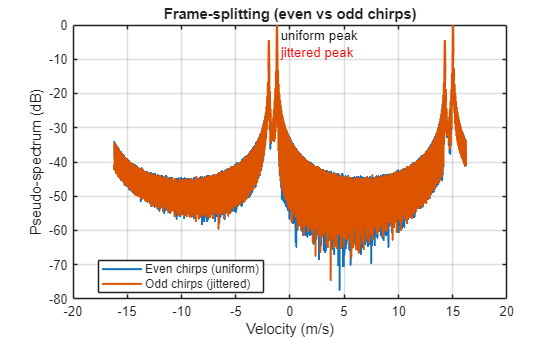

plot_scr_frame_splitting_mitigation(rxDataCube_samplesByChirpsByRx, scrConfig);

### Functions

function plot_scr_frame_splitting_mitigation(rxDataCube, scrConfig)
% Compare even (uniform) vs odd (jittered) chirps at the strongest range bin.

speedOfLight_mps = physconst('LightSpeed');

[numAdcSamplesPerChirp, numChirpsPerFrame, ~] = size(rxDataCube);

chirpRampTime_s     = scrConfig.T_ramp;
idleTimeUniform_s   = scrConfig.T_idle_uniform;
idleTimeJitter_s    = scrConfig.T_idle_jitter;

chirpStartTime_s    = zeros(numChirpsPerFrame,1);
chirpDuration_s     = zeros(numChirpsPerFrame,1);

for chirpIndex = 1:numChirpsPerFrame
    if mod(chirpIndex,2)==0
        idleTimeThisChirp_s = idleTimeUniform_s;
    else
        idleTimeThisChirp_s = idleTimeUniform_s + (2*rand-1)*idleTimeJitter_s;
    end

    chirpDuration_s(chirpIndex) = chirpRampTime_s + idleTimeThisChirp_s;

    if chirpIndex == 1
        chirpStartTime_s(chirpIndex) = 0;
    else
        chirpStartTime_s(chirpIndex) = chirpStartTime_s(chirpIndex-1) + chirpDuration_s(chirpIndex-1);
    end
end

evenChirpIndices = 2:2:numChirpsPerFrame;
oddChirpIndices  = 1:2:numChirpsPerFrame;

evenChirpTimes_s = chirpStartTime_s(evenChirpIndices);
oddChirpTimes_s  = chirpStartTime_s(oddChirpIndices);

fastTimeWindow   = hann(numAdcSamplesPerChirp);
rangeFftCube     = fft(rxDataCube .* fastTimeWindow, scrConfig.Nfft_range, 1);
numRangeBins     = scrConfig.Nfft_range;

rangeFftCube     = rangeFftCube(1:numRangeBins,:,:);
rangeFftSumRx    = sum(rangeFftCube,3);

[~, strongestRangeBin] = max(max(abs(rangeFftSumRx), [], 2));

slowTimeEven = rangeFftSumRx(strongestRangeBin, evenChirpIndices);
slowTimeOdd  = rangeFftSumRx(strongestRangeBin, oddChirpIndices);

meanChirpTime_s = mean(chirpDuration_s);
maxDoppler_Hz   = 1/(2*meanChirpTime_s);
fineDopplerAxis_Hz = linspace(-maxDoppler_Hz, maxDoppler_Hz, scrConfig.Nv_fine).';

steeringEven = exp(1j*2*pi * fineDopplerAxis_Hz * evenChirpTimes_s(:).');
steeringOdd  = exp(1j*2*pi * fineDopplerAxis_Hz * oddChirpTimes_s(:).');

spectrumEven = abs(steeringEven * slowTimeEven.').^2;
spectrumOdd  = abs(steeringOdd  * slowTimeOdd.').^2;

wavelength_m = speedOfLight_mps / scrConfig.fc;
velocityAxis_mps = fineDopplerAxis_Hz * (wavelength_m/2);

spectrumEven_dB = 10*log10(spectrumEven / max(spectrumEven));
spectrumOdd_dB  = 10*log10(spectrumOdd  / max(spectrumOdd));

[~, peakIdxEven] = max(spectrumEven);
[~, peakIdxOdd]  = max(spectrumOdd);

peakVelEven_mps  = velocityAxis_mps(peakIdxEven);
peakVelOdd_mps   = velocityAxis_mps(peakIdxOdd);

figure('Color','w','Name','SCR frame-splitting spoofing mitigation')
plot(velocityAxis_mps, spectrumEven_dB, 'LineWidth', 1.5)
hold on
plot(velocityAxis_mps, spectrumOdd_dB,  'LineWidth', 1.5)
grid on
xlabel('Velocity (m/s)'); ylabel('Pseudo-spectrum (dB)')
title('Frame-splitting (even vs odd chirps)')
legend({'Even chirps (uniform)','Odd chirps (jittered)'}, 'Location','best')

yLimits = ylim;
text(peakVelEven_mps, yLimits(2)-3, ' uniform peak', 'Color','k', 'HorizontalAlignment','left');
text(peakVelOdd_mps,  yLimits(2)-8, ' jittered peak', 'Color','r', 'HorizontalAlignment','left');
ylim(yLimits);
end

function plot_scr_spoofing_mitigation(rxDataCube, scrConfig)
% Display chirp-splitting mismatch with a spoofer

speedOfLight_mps = physconst('LightSpeed');

[numAdcSamplesPerChirp, numChirpsPerFrame, ~] = size(rxDataCube);
numSamplesHalfChirp = numAdcSamplesPerChirp/2;

chirpRampTime_s   = scrConfig.T_ramp;
idleTimeUniform_s = scrConfig.T_idle_uniform;
idleTimeJitter_s  = scrConfig.T_idle_jitter;

chirpStartTime_s  = zeros(numChirpsPerFrame,1);
chirpDuration_s   = zeros(numChirpsPerFrame,1);

for chirpIndex = 1:numChirpsPerFrame
    if mod(chirpIndex,2)==0
        idleTimeThisChirp_s = idleTimeUniform_s;
    else
        idleTimeThisChirp_s = idleTimeUniform_s + (2*rand-1)*idleTimeJitter_s;
    end

    chirpDuration_s(chirpIndex) = chirpRampTime_s + idleTimeThisChirp_s;

    if chirpIndex == 1
        chirpStartTime_s(chirpIndex) = 0;
    else
        chirpStartTime_s(chirpIndex) = chirpStartTime_s(chirpIndex-1) + chirpDuration_s(chirpIndex-1);
    end
end

fastTimeWindow   = hann(numAdcSamplesPerChirp);
rangeFftCube     = fft(rxDataCube .* fastTimeWindow, scrConfig.Nfft_range, 1);
numRangeBins     = scrConfig.Nfft_range;
rangeFftCube     = rangeFftCube(1:numRangeBins,:,:);
rangeFftSumRx    = sum(rangeFftCube,3);

[~, strongestRangeBin] = max(max(abs(rangeFftSumRx), [], 2));

rxLowerHalf = rxDataCube(1:numSamplesHalfChirp,:,:);
rxUpperHalf = rxDataCube(numAdcSamplesPerChirp-numSamplesHalfChirp+1:numAdcSamplesPerChirp,:,:);

lowerHalfFft = fft(rxLowerHalf .* hann(numSamplesHalfChirp), scrConfig.Nfft_range, 1);
upperHalfFft = fft(rxUpperHalf .* hann(numSamplesHalfChirp), scrConfig.Nfft_range, 1);

lowerHalfFft = sum(lowerHalfFft(1:numRangeBins,:,:),3);
upperHalfFft = sum(upperHalfFft(1:numRangeBins,:,:),3);

slowTimeLower = lowerHalfFft(strongestRangeBin,:);
slowTimeUpper = upperHalfFft(strongestRangeBin,:);

meanChirpTime_s = mean(chirpDuration_s);
maxDoppler_Hz   = 1/(2*meanChirpTime_s);
fineDopplerAxis_Hz = linspace(-maxDoppler_Hz, maxDoppler_Hz, scrConfig.Nv_fine).';

slowTimeAxis_s  = chirpStartTime_s(:).';

steeringUpper = exp(1j*2*pi*fineDopplerAxis_Hz * slowTimeAxis_s);

lowerCenterCarrier_Hz = scrConfig.fc + scrConfig.k_slope * scrConfig.t0_lower;
upperCenterCarrier_Hz = scrConfig.fc + scrConfig.k_slope * scrConfig.t0_upper;
carrierRatio          = lowerCenterCarrier_Hz / upperCenterCarrier_Hz;

steeringLowerScaled = exp(1j*2*pi*(carrierRatio*fineDopplerAxis_Hz) * slowTimeAxis_s);

spectrumUpper = abs(steeringUpper      * slowTimeUpper.').^2;
spectrumLower = abs(steeringLowerScaled* slowTimeLower.').^2;

wavelength_m = speedOfLight_mps / scrConfig.fc;
velocityAxis_mps = fineDopplerAxis_Hz * (wavelength_m/2);

[~, peakIdxUpper] = max(spectrumUpper);
[~, peakIdxLower] = max(spectrumLower);

peakVelUpper_mps  = velocityAxis_mps(peakIdxUpper);
peakVelLower_mps  = velocityAxis_mps(peakIdxLower);

figure('Color','w','Name','SCR spoofing mitigation (chirp-splitting)')
plot(velocityAxis_mps, 10*log10(spectrumUpper / max(spectrumUpper)), 'LineWidth', 1.5)
hold on
plot(velocityAxis_mps, 10*log10(spectrumLower / max(spectrumLower)), 'LineWidth', 1.5)
grid on
xlabel('Velocity (m/s)'); ylabel('Pseudo-spectrum (dB)')
title('Chirp-splitting at strongest target')
legend({'Upper half chirps','Lower half chirps'}, 'Location','best')

yLimits = ylim;
text(peakVelUpper_mps, yLimits(2)-3, ' Upper peak', 'Color','k', 'HorizontalAlignment','left')
text(peakVelLower_mps, yLimits(2)-8, ' Lower peak', 'Color','r', 'HorizontalAlignment','left')
ylim(yLimits);
end

function scrOutput = scr_run_frame(rxDataCube, scrConfig)
% Calculate SCR velocity/distance modulation metrics for one frame

speedOfLight_mps = physconst('LightSpeed');

[numAdcSamplesPerChirp, numChirpsPerFrame, ~] = size(rxDataCube);
assert(mod(numAdcSamplesPerChirp,2)==0,'SCR assumes an even number of ADC samples per chirp.');
numSamplesHalfChirp = numAdcSamplesPerChirp/2;

chirpRampTime_s     = scrConfig.T_ramp;
idleTimeUniform_s   = scrConfig.T_idle_uniform;
idleTimeJitter_s    = scrConfig.T_idle_jitter;

chirpStartTime_s    = zeros(numChirpsPerFrame,1);
chirpDuration_s     = zeros(numChirpsPerFrame,1);

for chirpIndex = 1:numChirpsPerFrame
    if mod(chirpIndex,2)==0
        idleTimeThisChirp_s = idleTimeUniform_s;
    else
        idleTimeThisChirp_s = idleTimeUniform_s + (2*rand-1)*idleTimeJitter_s;
    end

    chirpDuration_s(chirpIndex) = chirpRampTime_s + idleTimeThisChirp_s;

    if chirpIndex == 1
        chirpStartTime_s(chirpIndex) = 0;
    else
        chirpStartTime_s(chirpIndex) = chirpStartTime_s(chirpIndex-1) + chirpDuration_s(chirpIndex-1);
    end
end

oddChirpIndices  = 1:2:numChirpsPerFrame;
evenChirpIndices = 2:2:numChirpsPerFrame;

fastTimeWindow   = hann(numAdcSamplesPerChirp);
rangeFftCube     = fft(rxDataCube .* fastTimeWindow, scrConfig.Nfft_range, 1);
numRangeBins     = scrConfig.Nfft_range;
rangeFftCube     = rangeFftCube(1:numRangeBins,:,:);

adcSampleRate_Hz = scrConfig.fs_adc;
chirpSlope_HzPerS= scrConfig.k_slope;
rangeFreqRes_Hz  = adcSampleRate_Hz / scrConfig.Nfft_range;

scrOutput.range_axis = (0:numRangeBins-1).' * (speedOfLight_mps*rangeFreqRes_Hz/(2*chirpSlope_HzPerS));

rangeFftSumRx    = sum(rangeFftCube,3);
meanChirpTime_s  = mean(chirpDuration_s);
numVelBins       = scrConfig.Nfft_doppler;

velocityFft = fftshift(fft(rangeFftSumRx.', numVelBins, 1),1).';
scrOutput.RD_standard = abs(velocityFft);

wavelength_m = speedOfLight_mps / scrConfig.fc;
maxDoppler_Hz = 1/(2*meanChirpTime_s);
scrOutput.vel_axis = linspace(-maxDoppler_Hz, maxDoppler_Hz, numVelBins).' * (wavelength_m/2);

rxLowerHalf = rxDataCube(1:numSamplesHalfChirp,:,:);
rxUpperHalf = rxDataCube(numAdcSamplesPerChirp-numSamplesHalfChirp+1:numAdcSamplesPerChirp,:,:);

lowerHalfFft = fft(rxLowerHalf .* hann(numSamplesHalfChirp), scrConfig.Nfft_range, 1);
upperHalfFft = fft(rxUpperHalf .* hann(numSamplesHalfChirp), scrConfig.Nfft_range, 1);

lowerHalfFft = lowerHalfFft(1:numRangeBins,:,:);
upperHalfFft = upperHalfFft(1:numRangeBins,:,:);

lowerHalfFftSumRx = sum(lowerHalfFft,3);
upperHalfFftSumRx = sum(upperHalfFft,3);

lowerCenterCarrier_Hz = scrConfig.fc + scrConfig.k_slope * scrConfig.t0_lower;
upperCenterCarrier_Hz = scrConfig.fc + scrConfig.k_slope * scrConfig.t0_upper;
carrierRatio          = lowerCenterCarrier_Hz / upperCenterCarrier_Hz;

fineDopplerAxis_Hz = linspace(-maxDoppler_Hz, maxDoppler_Hz, scrConfig.Nv_fine).';

[peakRangeBins, ~] = simple_peak_picker(scrOutput.RD_standard, scrConfig.RD_threshold);

[velMetric_Hz, velIsBackscatter] = scr_detect_velocity_mod( ...
    lowerHalfFftSumRx, upperHalfFftSumRx, chirpStartTime_s, fineDopplerAxis_Hz, carrierRatio, peakRangeBins, scrConfig);

scrOutput.velModMetric        = velMetric_Hz;
scrOutput.velModIsBackscatter = velIsBackscatter;

rangeFftEven = rangeFftSumRx(:,evenChirpIndices);
rangeFftOdd  = rangeFftSumRx(:,oddChirpIndices);

evenChirpTimes_s = chirpStartTime_s(evenChirpIndices);
oddChirpTimes_s  = chirpStartTime_s(oddChirpIndices);

[distMetric_norm, distIsBackscatter] = scr_detect_distance_mod( ...
    rangeFftOdd, oddChirpTimes_s, rangeFftEven, evenChirpTimes_s, fineDopplerAxis_Hz, peakRangeBins, scrConfig);

scrOutput.distModMetric        = distMetric_norm;
scrOutput.distModIsBackscatter = distIsBackscatter;
end

function [metric_Hz, isBackscatter] = scr_detect_velocity_mod(lowerHalfRangeFft, upperHalfRangeFft, chirpStartTime_s, fineDopplerAxis_Hz, carrierRatio, peakRangeBins, scrConfig)

[numRangeBins, ~] = size(upperHalfRangeFft);
numPeaks = numel(peakRangeBins);

metric_Hz      = zeros(numPeaks,1);
isBackscatter  = false(numPeaks,1);

slowTimeRow_s  = chirpStartTime_s(:).';
steeringUpper  = exp(1j*2*pi*fineDopplerAxis_Hz * slowTimeRow_s);
steeringLower  = exp(1j*2*pi*(carrierRatio*fineDopplerAxis_Hz) * slowTimeRow_s);

dopplerBinWidth_Hz = fineDopplerAxis_Hz(2) - fineDopplerAxis_Hz(1);

for peakIndex = 1:numPeaks
    rangeBin = peakRangeBins(peakIndex);
    if rangeBin < 1 || rangeBin > numRangeBins, continue; end

    slowTimeUpper = upperHalfRangeFft(rangeBin,:);
    slowTimeLower = lowerHalfRangeFft(rangeBin,:);

    spectrumUpper = abs(steeringUpper * slowTimeUpper.').^2;
    spectrumLower = abs(steeringLower * slowTimeLower.').^2;

    [~, peakUpperIdx] = max(spectrumUpper);
    [~, peakLowerIdx] = max(spectrumLower);

    peakShift_Hz = abs(peakLowerIdx - peakUpperIdx) * dopplerBinWidth_Hz;

    metric_Hz(peakIndex)     = peakShift_Hz;
    isBackscatter(peakIndex) = (peakShift_Hz > scrConfig.velShiftThresh_Hz);
end
end

function [metric_norm, isBackscatter] = scr_detect_distance_mod(oddGroupRangeFft, oddGroupTimes_s, evenGroupRangeFft, evenGroupTimes_s, fineDopplerAxis_Hz, peakRangeBins, scrConfig) %#ok<INUSD>

[numRangeBins, ~] = size(oddGroupRangeFft);
numPeaks = numel(peakRangeBins);

metric_norm    = zeros(numPeaks,1);
isBackscatter  = false(numPeaks,1);

steeringEven = exp(1j*2*pi*fineDopplerAxis_Hz * evenGroupTimes_s(:).');
steeringOdd  = exp(1j*2*pi*fineDopplerAxis_Hz * oddGroupTimes_s(:).');

for peakIndex = 1:numPeaks
    rangeBin = peakRangeBins(peakIndex);
    if rangeBin < 1 || rangeBin > numRangeBins, continue; end

    slowTimeEven = evenGroupRangeFft(rangeBin,:);
    slowTimeOdd  = oddGroupRangeFft(rangeBin,:);

    spectrumEven = abs(steeringEven * slowTimeEven.').^2;
    spectrumOdd  = abs(steeringOdd  * slowTimeOdd.').^2;

    peakEven = max(spectrumEven);
    peakOdd  = max(spectrumOdd);

    if peakEven <= 0
        metric_norm(peakIndex) = 0;
        isBackscatter(peakIndex) = false;
    else
        peakMagDiff = abs(peakEven - peakOdd) / peakEven;
        metric_norm(peakIndex) = peakMagDiff;
        isBackscatter(peakIndex) = (peakMagDiff > scrConfig.distMagDiffThresh);
    end
end
end

function [peakRangeBins, peakVelBins] = simple_peak_picker(rdMagnitudeMap, thresholdBelowMax_dB)
rd_dB   = 20*log10(rdMagnitudeMap + eps);
max_dB  = max(rd_dB(:));
mask    = rd_dB > (max_dB + thresholdBelowMax_dB);
[peakRangeBins, peakVelBins] = find(mask);
end
